This example compares the performance of various c2d approaches for a simple filtering problem.  Let's look at 3rd order filter with a notch at 2/3 of the Nyquist frequency.

T = 0.5;
w_notch = 2*pi/T/3;
H = tf(1,[1 2 2 1])*tf([1 2*.1*w_notch w_notch^2],[1 2*.01*w_notch w_notch^2]);

Now I'll generate various approximations using brute force for some, and c2d for most.  For the forward and backward integration approaches I have no choice.

[A,B,C,D] = ssdata(H);
n = length(B);
Hf = ss(eye(n)+A*T,B*T,C,D,T);
Hb = ss(inv(eye(n)-A*T),inv(eye(n)-A*T)*B*T,C*inv(eye(n)-A*T),D+C*inv(eye(n)-A*T)*B*T,T);

The rest are simply created via c2d.  You might be thinking it's not a good sign that forward and backward are not simply options in c2d - you are right.  They don't work well.

Ht = c2d(H,T,'tustin');
Hpz = c2d(H,T,'matched');
Hfoh = c2d(H,T,'foh');

Now let's look at the results in the frequency domain.  I'll add the zero order hold result just for kicks.

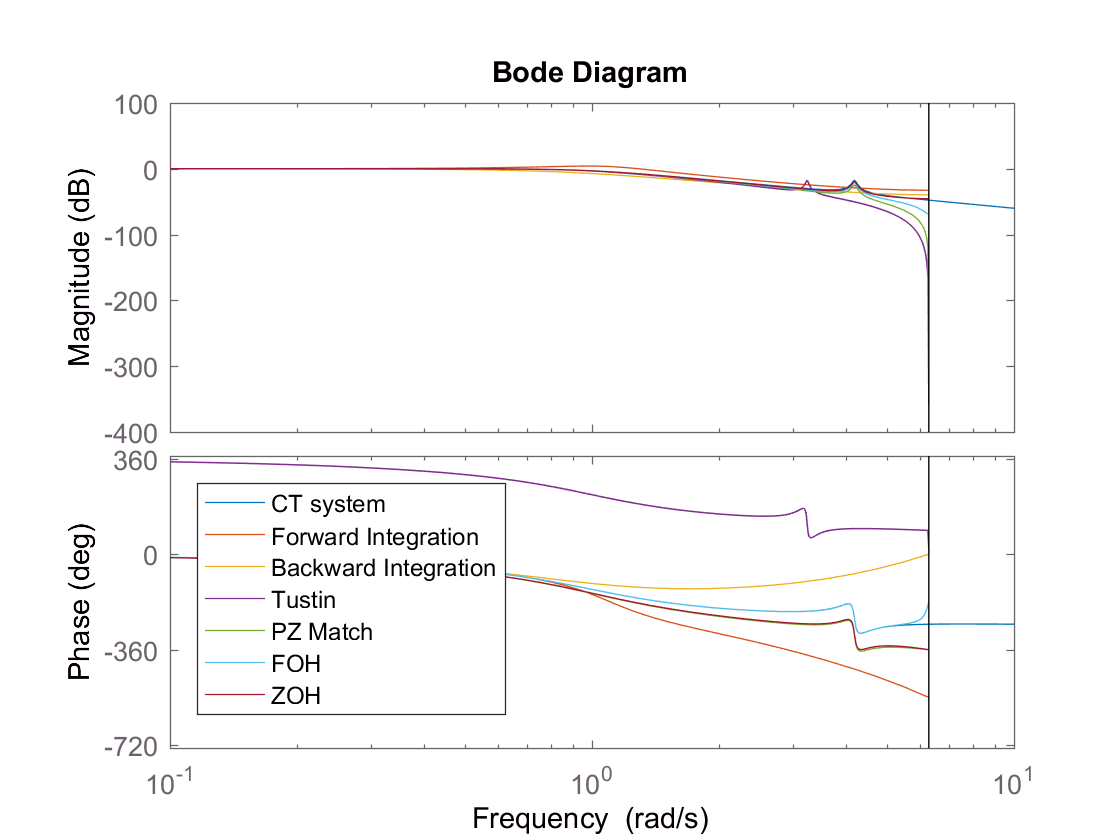

bode(H,Hf,Hb,Ht,Hpz,Hfoh,c2d(H,T),{0.1,10})
legend('CT system','Forward Integration','Backward Integration','Tustin','PZ Match','FOH','ZOH','Location','Northwest')

Clearly, both the forward and backward approximations are far off in phase - they are the most obvious,  but worst, choices.  Let's eliminate those and focus in on the notch performance.

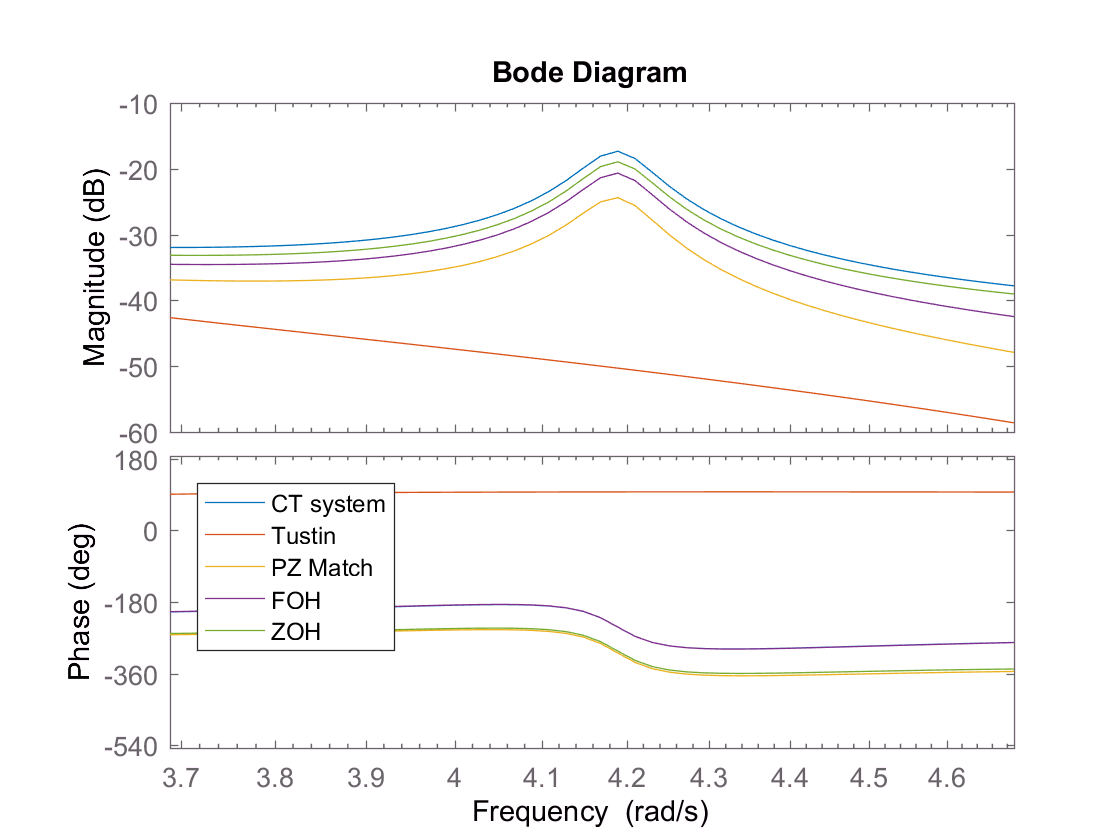

bode(H,Ht,Hpz,Hfoh,c2d(H,T),logspace(log10(w_notch-.5),log10(w_notch+.5)))
legend('CT system','Tustin','PZ Match','FOH','ZOH','Location','Northwest')

All seem to do a decent job except for Tustin, but Tustin is easy to fix.

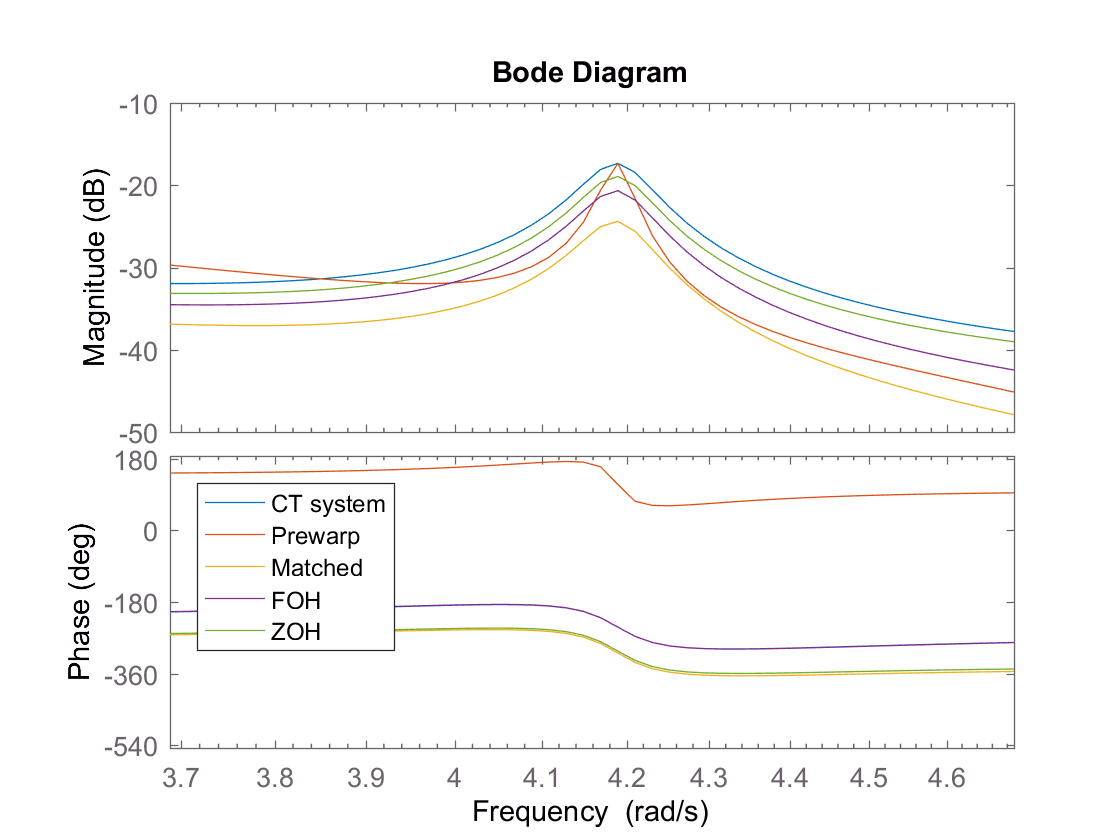

Hpw = c2d(H,T,'prewarp',w_notch);
bode(H,Hpw,Hpz,Hfoh,c2d(H,T),logspace(log10(w_notch-.5),log10(w_notch+.5)))
legend('CT system','Prewarp','Matched','FOH','ZOH','Location','Northwest')

From this simple example, I have a suggestion.  The FOH method is the "best" - it tracks the phase very well and does a good job reconstructing the magnitude.  It was my go-to emulation approach throughout the years, and has not failed me yet.  Unless you are approximating a nonlinear controller, I highly recommend it.  IF you are going nonlinear, Tustin is a good method for solving the ODE.